## Udarbejdelse af model

Der udarbejdes en model for pitch --> picth på baggrund af et step fra 0 grader til 30 grader.

Input er i grader. Outout er i radianer.

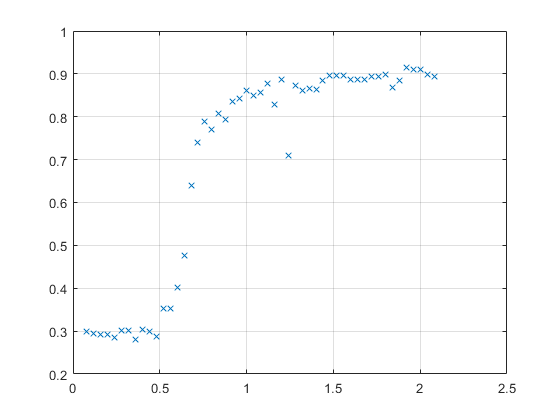

meas30 = csvread('30pitch2.csv',3);

t30=meas30(:,1);
x30=meas30(:,2);
y30=meas30(:,3);

angle30 = atan(y30./x30);
angle30=-angle30;               %Positive step response
plot(t30,angle30,'X')
grid on

Det vuderes visulet at målingen er forskydt 0,3 rad i forhold til vandret. Dette skyldes måleteknikken i Physlet Tracker. Dette juststeres der for.

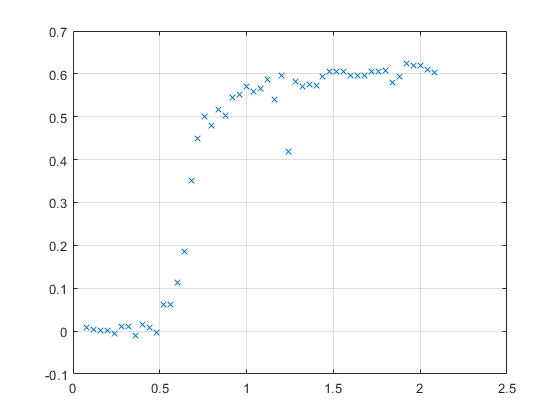

angle2_30=angle30-0.29;
plot(t30,angle2_30,'X');
grid on

Dette vurderes udmiddelbart som et første orden system. 

Derfor kan DC-forstærkningen aflæses til $\textrm{K1}=0,60\ldotp$ Fordi der er givet et step på på 30 grader divides der med 30. $K=\frac{\;0\ldotp 6}{30}=0\ldotp 02$

Det vurderes at stigningen begynder i $t=0,5$ og når cirka 98,2 % i $t=0,5$. Dermed vil tidskonstanten være $\tau =\frac{\;1\ldotp 1}{5}=0\ldotp 2\;\mathrm{s}$

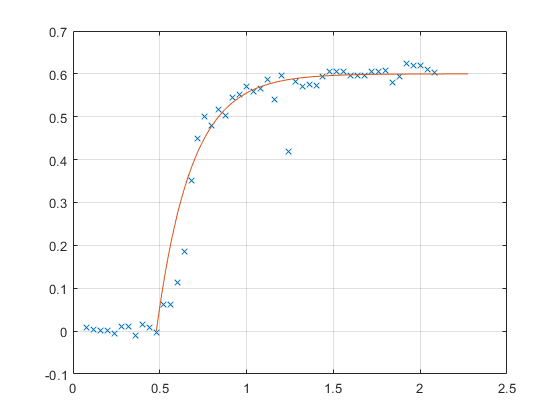

K=0.02;
tau=0.2;

s=tf('s');      %Variabel i overførselsfunktioner
G=K/(tau*s+1);  %Overførselsfunktionen

optStep30 = stepDataOptions('InputOffset',0,'StepAmplitude',30);    %Step respons step lig 30 grader
[Y t2_30]= step(G,optStep30);


plot(t30,angle2_30,'X',t2_30+0.48,Y)
%xlim([0 0.7])
grid on

## Kontrol af model

Modellen kontrolleres ved at se om den matcher på et step på 0 grader til 10 grader.

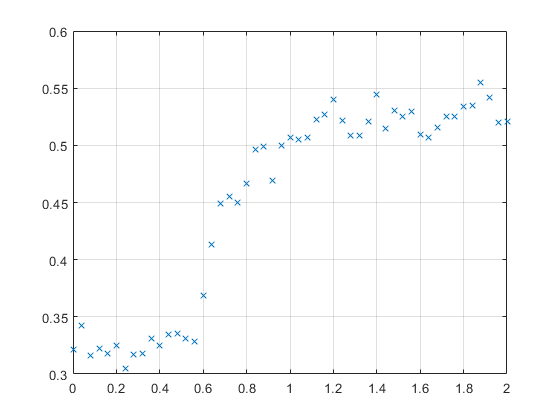

meas10 = csvread('10pitch.csv',2);

t10=meas10(:,1);
x10=meas10(:,2);
y10=meas10(:,3);

angle10 = atan(y10./x10);
angle10=-angle10;               %Positive step response
plot(t10,angle10,'X')
grid on

Dene  graf forskydes til 0.

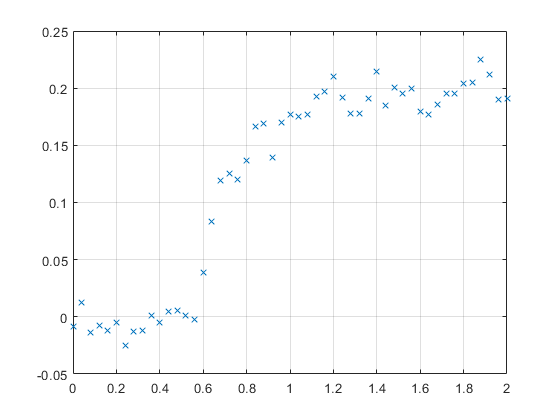

angle10_2=angle10-0.33;
plot(t10,angle10_2,'X')
grid on

Det vuderes at steppet begynder i $t=0,233$. Plotter model sammen med.

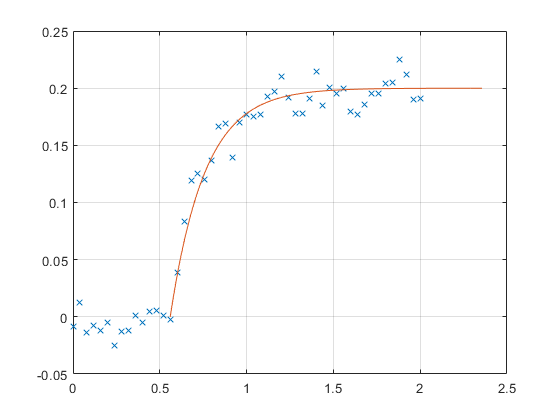

optStep10 = stepDataOptions('InputOffset',0,'StepAmplitude',10);    %Step respons step lig 10 grader
[Y10 t2_10]= step(G,optStep10);

plot(t10,angle10_2,'X',t2_10+0.56,Y10)
grid on

Det ses at modellen passer.

## Pæne plots til rapport

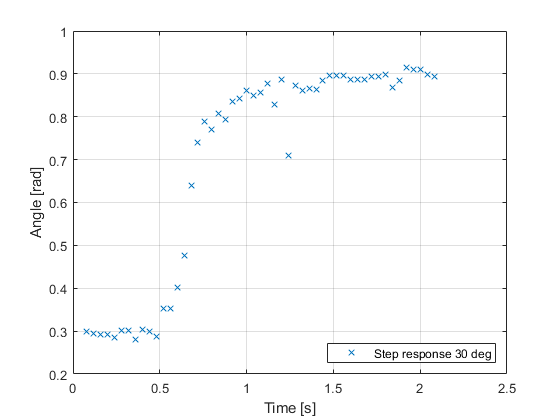

plot(t30,angle30,'X')
grid on
ylabel("Angle [rad]")
xlabel("Time [s]")
legend("Step response 30 deg",'Location','southeast')
exportgraphics(gcf,'stepPitchUnProcessed.pdf','ContentType','vector')

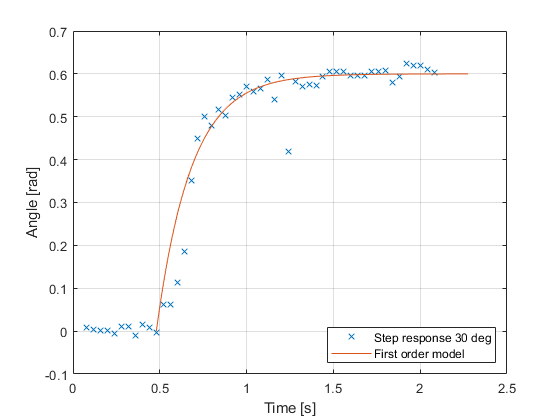

plot(t30,angle2_30,'X',t2_30+0.48,Y)
grid on
ylabel("Angle [rad]")
xlabel("Time [s]")
legend("Step response 30 deg","First order model",'Location','southeast')
exportgraphics(gcf,'stepPitch30.pdf','ContentType','vector')

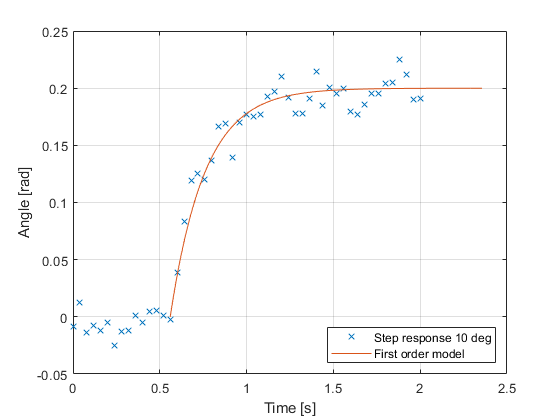

plot(t10,angle10_2,'X',t2_10+0.56,Y10)
grid on
ylabel("Angle [rad]")
xlabel("Time [s]")
legend("Step response 10 deg","First order model",'Location','southeast')
exportgraphics(gcf,'stepPitch10.pdf','ContentType','vector')